Project

Euler's method

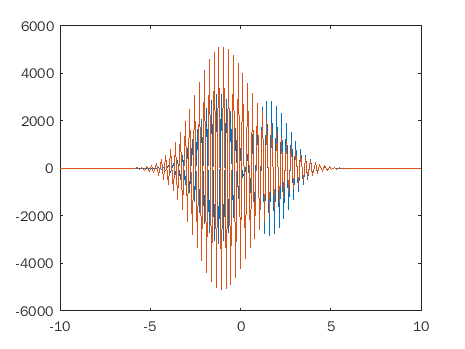

a=-5;
b=5;
sigma=2;
T=10^-12;
m_arr=[10 20 40 80 160];
N_arr=[25 50 100 200 400];
err=zeros(size(m_arr));

funinit=@(x) exp(-(x/sigma).^2);

for i=1:length(m_arr)
    m=m_arr(i);
    N=N_arr(i);
    h=1/(m+1);
    k=T/N;
    x=linspace(a,b,m+1);
    x2=linspace(a,b,m*2+1);
    Us=zeros([m+1, N+1]);
    Us2=zeros([m*2+1, N+1]);
    Us(:,1)=funinit(x);
    Us2(:,1)=funinit(x2);
    
    for j=1:N
        Un=Us(:,j);
        Unp=eustep(Un,k,h,m+1);
        Us(:,j+1)=Unp;
    end
    
    for j=1:N*2
        Un2=Us2(:,j);
        Unp2=eustep(Un2,k/2,h/2,m*2+1);
        Us2(:,j+1)=Unp2;

    end
    
    err(i)=max(abs(Un-Un2(1:2:2*m+1)));

end
ratio = err(1:end-1)./err(2:end);
p=log(ratio)/log(2);
fprintf('%5i & %5i & %9.2e & %5.2f & %5.2f \n', [m_arr; N_arr; err; [0 ratio]; [0 p]])


Leapfrog

a=-5;

   10 &  0.05 &  0.05
3.250000e+01 &  0.12 &  0.12
   55 &  0.82 &  0.81
7.750000e+01 &  0.91 &  0.92
  100 &  0.99 &  1.00


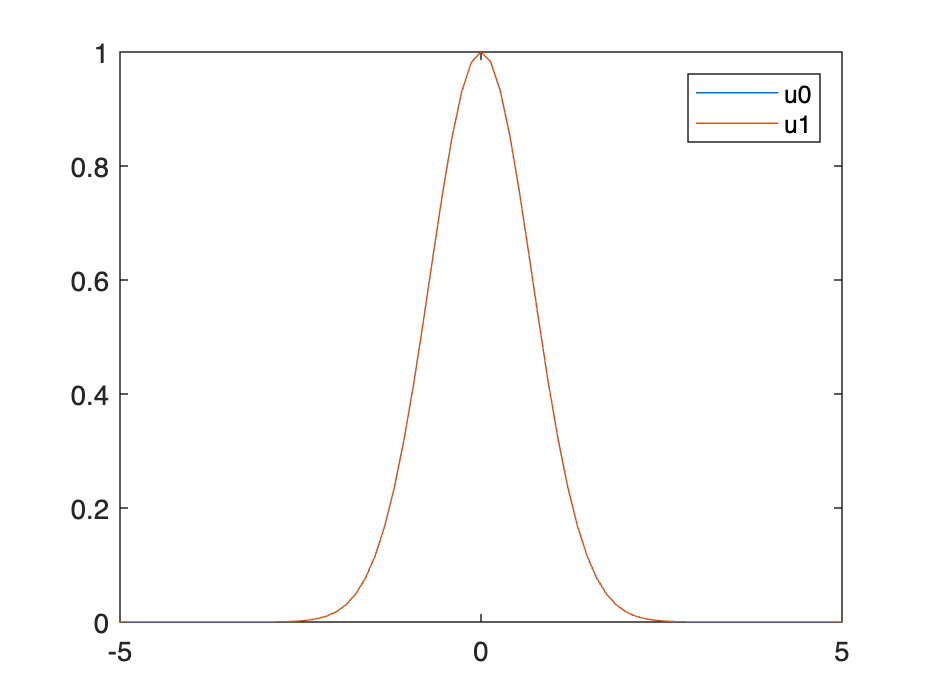

b=5;
sigma=2;
T=10^-5;
c=1.2;
m_arr=[10 20 40 80 160];

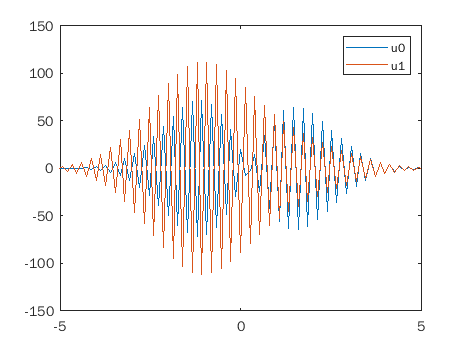

N_arr=[25 50 100 200 400];
err=zeros(size(m_arr));

funinit=@(x) exp(-(x/sigma).^2);

for i=1:length(m_arr)
    m=m_arr(i);
    N=N_arr(i);

    h=1/(m+1);

   10 &    25 &  2.60e-09 &  0.00 &  0.00 
   20 &    50 &  2.03e-09 &  1.28 &  0.36 
   40 &   100 &  2.00e-08 &  0.10 & -3.30 
   80 &   200 &  1.68e-07 &  0.12 & -3.07 
  160 &   400 &  1.33e-06 &  0.13 & -2.98 


   10 &    25 &  4.89e-07 &  0.00 &  0.00 
   20 &    50 &  7.52e-09 & 64.99 &  6.02 
   40 &   100 &  9.40e-09 &  0.80 & -0.32 
   80 &   200 &  3.71e-08 &  0.25 & -1.98 
  160 &   400 &  1.48e-07 &  0.25 & -1.99 


   10 &    25 &  1.23e-01 &  0.00 &  0.00 
   20 &    50 &  1.30e-01 &  0.95 & -0.08 
   40 &   100 &  1.33e-01 &  0.98 & -0.04 
   80 &   200 &  1.24e-01 &  1.07 &  0.10 
  160 &   400 &  9.85e-02 &  1.26 &  0.33 


   10 &    25 &  8.90e-09 &  0.00 &  0.00 
   20 &    50 &  7.28e-09 &  1.22 &  0.29 
   40 &   100 &  9.36e-09 &  0.78 & -0.36 
   80 &   200 &  3.71e-08 &  0.25 & -1.99 
  160 &   400 &  1.48e-07 &  0.25 & -1.99 


    k=T/N;
    x=linspace(a,b,m+1);
    x2=linspace(a,b,m*2+1);
    Us=zeros([m+1, N+2]);
    Us2=zeros([m*2+1, N+2]);
    Us(:,1)=funinit(x);
    Us2(:,1)=funinit(x2);
    Us(:,2)=Us(:,1)-c*k;
    Us2(:,2)=Us2(:,1)-c*k;
    
    for j=1:N
        Un=Us(:,j+1);
        Unm1=Us(:,j);
        Unp=leapfrogstep(Un,Unm1,k,h,m+1);
        Us(:,j+2)=Unp;
    end
    
    for j=1:N*2
        Un2=Us2(:,j+1);
        Unm12=Us2(:,j);
        Unp2=leapfrogstep(Un2,Unm12,k/2,h/2,m*2+1);
        Us2(:,j+2)=Unp2;
    end
    
    err(i)=max(abs(Un-Un2(1:2:2*m+1)));

end
ratio = err(1:end-1)./err(2:end);
p=log(ratio)/log(2);
fprintf('%5i & %5i & %9.2e & %5.2f & %5.2f \n', [m_arr; N_arr; err; [0 ratio]; [0 p]])


Lax-Friedrichs

a=-5;
b=5;
sigma=2;
T=10^-15;
m_arr=[10 20 40 80 160];
N_arr=[25 50 100 200 400];
err=zeros(size(m_arr));

funinit=@(x) exp(-(x/sigma).^2);

for i=1:length(m_arr)
    m=m_arr(i);
    N=N_arr(i);
    h=1/(m+1);
    k=T/N;
    x=linspace(a,b,m+1);
    x2=linspace(a,b,m*2+1);
    Us=zeros([m+1, N+1]);
    Us2=zeros([m*2+1, N+1]);
    Us(:,1)=funinit(x);
    Us2(:,1)=funinit(x2);
    
    for j=1:N
        Un=Us(:,j);
        Unp=lfstep(Un,k,h,m+1);
        Us(:,j+1)=Unp;
    end
    
    for j=1:N*2
        Un2=Us2(:,j);
        Unp2=lfstep(Un2,k/2,h/2,m*2+1);
        Us2(:,j+1)=Unp2;
    end
    
    err(i)=max(abs(Un-Un2(1:2:2*m+1)));

end
ratio = err(1:end-1)./err(2:end);
p=log(ratio)/log(2);
fprintf('%5i & %5i & %9.2e & %5.2f & %5.2f \n', [m_arr; N_arr; err; [0 ratio]; [0 p]])


Lax-Wendroff

a=-5;
b=5;
sigma=2;
T=10^-5;
m_arr=[10 20 40 80 160];
N_arr=[25 50 100 200 400];
err=zeros(size(m_arr));

funinit=@(x) exp(-(x/sigma).^2);

for i=1:length(m_arr)
    m=m_arr(i);
    N=N_arr(i);
    h=1/(m+1);
    k=T/N;
    x=linspace(a,b,m+1);
    x2=linspace(a,b,m*2+1);
    Us=zeros([m+1, N+1]);
    Us2=zeros([m*2+1, N+1]);
    Us(:,1)=funinit(x);
    Us2(:,1)=funinit(x2);
    
    for j=1:N
        Un=Us(:,j);
        Unp=lwstep(Un,k,h,m+1);
        Us(:,j+1)=Unp;
    end
    
    for j=1:N*2
        Un2=Us2(:,j);
        Unp2=lwstep(Un2,k/2,h/2,m*2+1);
        Us2(:,j+1)=Unp2;
    end
    
    err(i)=max(abs(Un-Un2(1:2:2*m+1)));

end
ratio = err(1:end-1)./err(2:end);
p=log(ratio)/log(2);
fprintf('%5i & %5i & %9.2e & %5.2f & %5.2f \n', [m_arr; N_arr; err; [0 ratio]; [0 p]])


Analysis of Chaotic Properties

a=-10;
b=10;
x0=0.001;
x1=0.002;
sigma=1;
T=7.5*10^-4;
m=150;
h=1/(m+1);
N=50;
k=T/N;

funinit0=@(x) exp(-((x-x0)/sigma).^2);
funinit1=@(x) exp(-((x-x1)/sigma).^2);
x=linspace(a,b,m+1);
Us0=zeros([m+1, N]);
Us1=zeros([m+1, N]);
Us0(:,1)=funinit0(x);
Us1(:,1)=funinit1(x);

figure
pplot=plot(x,Us0(:,1),x,Us1(:,1));
hold on
for i=1:N
    Un0=Us0(:,i);
    Unp0=lwstep(Un0,k,h,m+1);
    Us0(:,i+1)=Unp0;
    Un1=Us1(:,i);
    Unp1=lwstep(Un1,k,h,m+1);
    Us1(:,i+1)=Unp1;
    [pplot.YData] = deal(Unp0,Unp1);
    pause(0.5)
end

Calcluation and Plotting

p=linspace(10, 100, 10);
p0=zeros(size(p));
p1=zeros(size(p));
for i=1:length(p)
    p0(i)=percent(Us0(:,end-4),p(i));
    p1(i)=percent(Us1(:,end-4),p(i));
end
fprintf('%5i & %5.2f & %5.2f\n', [p; p0; p1])

figure
plot(x,Us0(:,1),x,Us1(:,1))
xlim([-5 5])
legend('u0','u1')

plot(x,Us0(:,end-12),x,Us1(:,end-12))
xlim([-5 5])
legend('u0','u1')

plot(x,Us0(:,end-4),x,Us1(:,end-4))
xlim([-5 5])
legend('u0','u1')


Helper Functions

function per=percent(Un,percentile)
% Calculate percentage of data points in and above the given grid (in percentage).
%
%                       Input arguments:
%
%  Un - data points
%  percentile - percentage the grid is representing
%
%                       Output arguments:
%
%  per - cumulative percentage.

    count=0;
    bound=max(Un)-(abs(max(Un)-min(Un))*percentile/100);
    for i=1:length(Un)
        if Un(i,1)>=bound
            count=count+1;
        end
    end
    per=count/length(Un);
end

function Unp1=eustep(Un,k,h,m)
% One step of Euler's method.
%
%                       Input arguments:
%
%  Un - array of u.
%  k - time step.
%  h - grid size.
%  m - total number of grid.
%
%                       Output arguments:
%
%  Unp1 - a vector of length m+1; solution of pde.
    e=ones(m,1);

    Tx=spdiags([e 0*e -e],-1:1,m,m);
    Tx(1,end)=1;
    Tx(end,1)=-1;

    Txx=spdiags([e -2*e e],-1:1,m,m);
    Txx(1,end)=1;
    Txx(end,1)=1;

    Txxxx=spdiags([e -4*e 6*e -4*e e],-2:2,m,m);
    Txxxx(1,end)=-4;
    Txxxx(end,1)=-4;
    Txxxx(2,end)=1;
    Txxxx(1,end-1)=1;
    Txxxx(end,2)=1;
    Txxxx(end-1,1)=1;

    Ux=abs(Tx*Un/(2*h));

    T1=(Ux).^2/2;
    T2=Txx*Un/h^2;
    T3=Txxxx*Un/h^4;

    A=-k*(T1+T2+T3);

    Unp1=Un+A;
end

function Unp1=leapfrogstep(Un,Unm1,k,h,m)
% One step of Leapfrog method.
%
%                       Input arguments:
%
%  Un - array of u.
%  Unm1 - array of u^n-1
%  k - time step.
%  h - grid size.
%  m - total number of grid.
%
%                       Output arguments:
%
%  Unp1 - a vector of length m+1; solution of pde.
    e=ones(m,1);

    Tx=spdiags([e 0*e -e],-1:1,m,m);
    Tx(1,end)=1;
    Tx(end,1)=-1;

    Txx=spdiags([e -2*e e],-1:1,m,m);
    Txx(1,end)=1;
    Txx(end,1)=1;

    Txxxx=spdiags([e -4*e 6*e -4*e e],-2:2,m,m);
    Txxxx(1,end)=-4;
    Txxxx(end,1)=-4;
    Txxxx(2,end)=1;
    Txxxx(1,end-1)=1;
    Txxxx(end,2)=1;
    Txxxx(end-1,1)=1;

    Ux=abs(Tx*Un/(2*h));

    T1=(Ux).^2/2;
    T2=Txx*Un/h^2;
    T3=Txxxx*Un/h^4;

    A=-k*(T1+T2+T3);

    Unp1=Unm1+2*k*A;
end

function Unp1=lfstep(Un,k,h,m)
% One step of L-F method.
%
%                       Input arguments:
%
%  Un - array of u.
%  k - time step.
%  h - grid size.
%  m - total number of grid.
%
%                       Output arguments:
%
%  Unp1 - a vector of length m+1; solution of pde.
    e=ones(m,1);

    Tx=spdiags([e 0*e -e],-1:1,m,m);
    Tx(1,end)=1;
    Tx(end,1)=-1;

    Txx=spdiags([e -2*e e],-1:1,m,m);
    Txx(1,end)=1;
    Txx(end,1)=1;

    Txxxx=spdiags([e -4*e 6*e -4*e e],-2:2,m,m);
    Txxxx(1,end)=-4;
    Txxxx(end,1)=-4;
    Txxxx(2,end)=1;
    Txxxx(1,end-1)=1;
    Txxxx(end,2)=1;
    Txxxx(end-1,1)=1;

    Ux=abs(Tx*Un/(2*h));

    T1=(Ux).^2/2;
    T2=Txx*Un/h^2;
    T3=Txxxx*Un/h^4;

    A=-k*(T1+T2+T3);

    Unp1=[Un(1,1); (Un(1:end-2,1)+Un(3:end,1))/2; Un(end,1)]+A;
end

function Unp1=lwstep(Un,k,h,m)
% One step of L-W method.
%
%                       Input arguments:
%
%  Un - array of u.
%  k - time step.
%  h - grid size.
%  m - total number of grid.
%
%                       Output arguments:
%
%  Unp1 - a vector of length m+1; solution of pde.
    e=ones(m,1);

    Tx=spdiags([e 0*e -e],-1:1,m,m);
    Tx(1,end)=1;
    Tx(end,1)=-1;

    Txx=spdiags([e -2*e e],-1:1,m,m);
    Txx(1,end)=1;
    Txx(end,1)=1;

    Txxxx=spdiags([e -4*e 6*e -4*e e],-2:2,m,m);
    Txxxx(1,end)=-4;
    Txxxx(end,1)=-4;
    Txxxx(2,end)=1;
    Txxxx(1,end-1)=1;
    Txxxx(end,2)=1;
    Txxxx(end-1,1)=1;

    Ux=abs(Tx*Un/(2*h));

    T1=(Ux).^2/2;
    T2=Txx*Un/h^2;
    T3=Txxxx*Un/h^4;

    TT1=T1.^2;
    TT2=Txx*T2/h^2;
    TT3=Txxxx*T3/h^4;

    A=-k*(T1+T2+T3);
    AA=-k^2*(TT1+TT2+TT3);

    Unp1=Un+k*A+k^2*AA/2;
end